# Modelagem SIR

Vinicius Urias da Cruz RA: 20.00601-2

## Boas Práticas

clear all;
close all;
clc;


## Leitura de Dados

data = csvread('SIRpd.csv', 1);

sd = data(:,1);
id = data(:,2);
rd = data(:,3);


## Definição de Variaveis Globais

global r beta 

## Geração de Ruído

sdMedia = mean(sd)/10;
idMedia = mean(sd)/5;
rdMedia = mean(sd)/10;

sdn = rand(length(sd), 1) * sdMedia;
idn = rand(length(id), 1) * idMedia;
rdn = rand(length(rd), 1) * rdMedia;

sdNew = sd + sdn;
idNew = id + idn;
rdNew = rd + rdn;


## Exibição de Gráficos

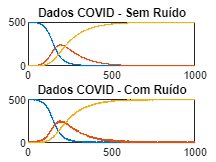

% eixo x 
tempo = linspace(0,length(sdNew),length(sdNew));
figure(1) 

% Gráfico sem ruído
subplot(2,1,1)
plot(tempo,sd, '.' , 'markersize',0.8)
hold on;
plot(tempo,id, '.' , 'markersize',0.8)
plot(tempo,rd, '.' , 'markersize',0.8)
hold off;
title('Dados COVID - Sem Ruído')

% Gráfico com ruído
subplot(2,1,2) 
plot(tempo,sdNew, '.' , 'markersize',0.8)
hold on;
plot(tempo, idNew, '.' , 'markersize',0.8)
plot(tempo, rdNew, '.' , 'markersize',0.8)
hold off;
title('Dados COVID - Com Ruído')

## Coleta de Dados Simulink

['Value'](matlab:Simulink.internal.OpenBlockParamsDialog(['ModeloSIR/beta'],'Value');)

R0       = 0;
S0       = 499;
I0       = 1;
r        = 0.1;
beta     = 0.001;
model    = sim("ModeloSIR.slx");

SdValues = model.logsout{1}.Values.Data;
IdValues = model.logsout{2}.Values.Data;
RdValues = model.logsout{3}.Values.Data;


## Calculo do Erro

% r        = X(1);
% beta     = X(2);
x0       = [r beta];
X        = fminsearch(@(x) ErroQuadratico(x,sdNew,idNew,rdNew), x0)

r = 0.1000

beta = 1.0000e-03

r = 0.1050

beta = 1.0000e-03

r = 0.1000

beta = 0.0011

r = 0.1050

beta = 9.5000e-04

r = 0.1013

beta = 0.0010

r = 0.1025

beta = 1.0000e-03

r = 0.1000

beta = 0.0010

r = 0.1025

beta = 9.7500e-04

r = 0.1006

beta = 0.0010

r = 0.1013

beta = 1.0000e-03

r = 0.1000

beta = 0.0010

r = 0.1013

beta = 9.8750e-04

r = 0.1003

beta = 0.0010

r = 0.1006

beta = 1.0000e-03

r = 0.1000

beta = 0.0010

r = 0.1006

beta = 9.9375e-04

r = 0.1002

beta = 0.0010

r = 0.1003

beta = 1.0000e-03

r = 0.1000

beta = 0.0010

r = 0.1003

beta = 9.9688e-04

r = 0.1001

beta = 0.0010

r = 0.1002

beta = 1.0000e-03

r = 0.1000

beta = 0.0010

r = 0.1002

beta = 9.9844e-04

r = 0.1000

beta = 0.0010

r = 0.1001

beta = 1.0000e-03

r = 0.1000

beta = 0.0010

X =     0.1000    0.0010


## TESTE DE COMPARAÇÂO

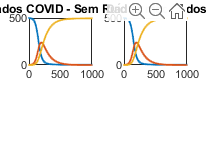

figure(2)

% Gráfico sem ruído
subplot(2,2,1)
plot(tempo,sd, '.' , 'markersize',0.8)
hold on;
plot(tempo,id, '.' , 'markersize',0.8)
plot(tempo,rd, '.' , 'markersize',0.8)
hold off;
title('Dados COVID - Sem Ruído')

% Gráfico com ruído
subplot(2,2,2) 
plot(tempo,SdValues, '.' , 'markersize',0.8)
hold on;
plot(tempo, IdValues, '.' , 'markersize',0.8)
plot(tempo, RdValues, '.' , 'markersize',0.8)
hold off;
title('Dados modelados')